# Probabilistic Principle Component Analysis For Time Delay Interferometry

Quentin Baghi has introduced a method to construct the TDI combinations with Principle Component Analysis (PCA). The travelling time of the light between two distant spacedracfts is not required in this method.

Now, we propose an method to form the TDI combinations with PCA from the perspective of probability, and it helps us to deal with the missing data case. We call this method as PPCA-TDI.

## Data Simulation

Like Baghi, we use the simulated data to validate the PPCATDI. The following equations show the noise requirements of LISA.

- Laser frequency noise: $S_{p}(f)=\left(\frac{28.2 \mathrm{~Hz} \cdot \mathrm{Hz}^{-1 / 2}}{\nu_{0}}\right)^{2},$

- Stochastic noise: $S_{n}(f)=\frac{S_{a}(f)}{(2 \pi f c)^{2}}+\left(\frac{2 \pi f}{c}\right)^{2} S_{\mathrm{oms}}(f),$

where $\nu_0 =\frac{c}{1064\times {10}^{-9} \;\mathrm{m}}$ is the central frequency of the lasers, $S_a \left(f\right)$ is the test-mass acceleration noise PSD (in ${\mathrm{m}}^2 {\mathrm{s}}^{-4} {\textrm{Hz}}^{-1}$) and $S_{\textrm{oms}} \left(f\right)$ is the PSD representing all other path length noises in the measurement (in ${\mathrm{m}}^2 {\textrm{Hz}}^{-1}$).

- Test-mass acceleration noise: $S_a \left(f\right)=a_{\textrm{TM}}^2 \left\lbrack 1+{\left(\frac{f_1 }{f}\right)}^2 \right\rbrack \left\lbrack 1+{\left(\frac{f}{f_2 }\right)}^4 \right\rbrack ,$

- Optical metrology system (OMS) noise: $S_{\textrm{oms}} \left(f\right)=a_{\textrm{oms}}^2 \left\lbrack 1+{\left(\frac{f_3 }{f}\right)}^4 \right\rbrack \ldotp$

where $a_{\mathrm{TM}} =3\times {10}^{-15} {\;\mathrm{ms}}^{-2} ,a_{\mathrm{oms}} =15\times {10}^{-12} {\;\mathrm{mHz}}^{-\frac{1}{2}} ,f_1 =4\times {10}^{-4} \;\mathrm{Hz},f_2 =8\times {10}^{-3} \;\mathrm{Hz},f_3 =2\times {10}^{-3} \;\mathrm{mHz}\ldotp$

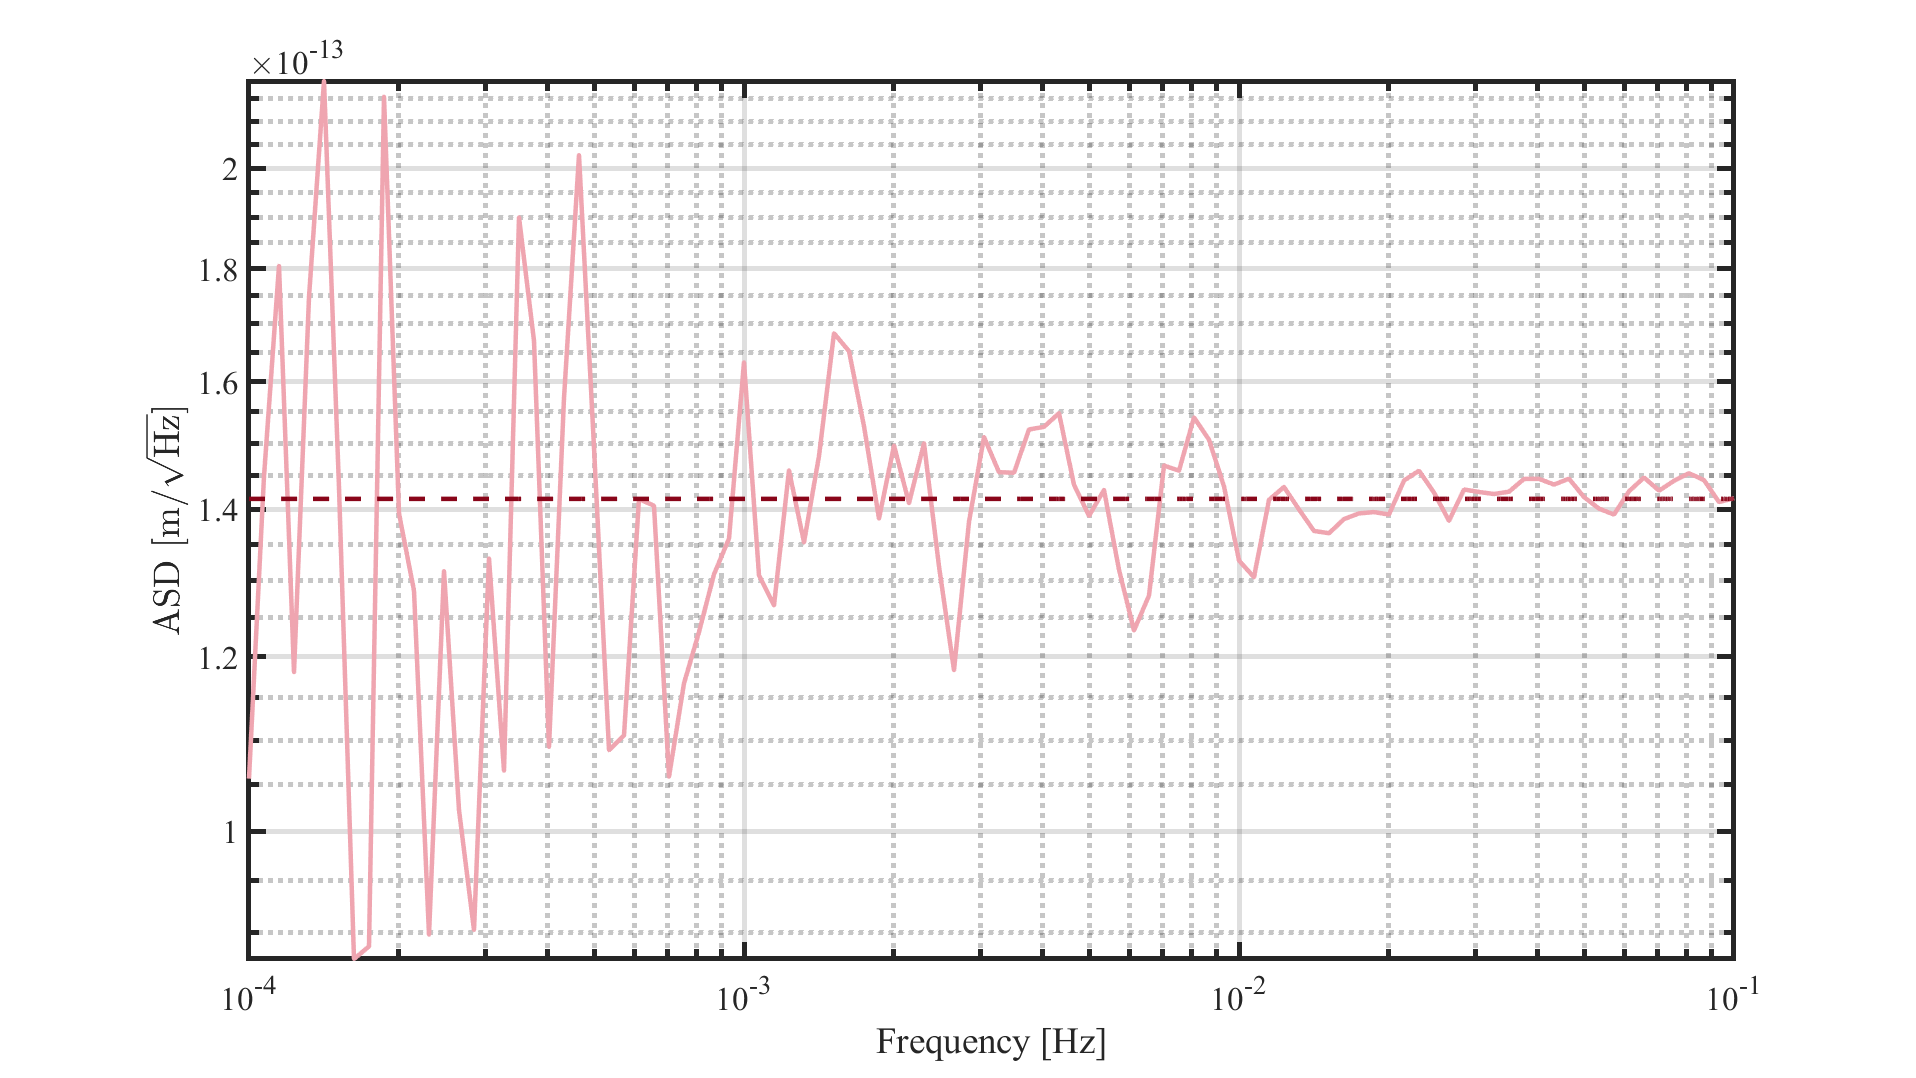

clc;
clear;
close all;
warning off;

% -------- %
% constant %
% -------- %
% simulation parameter
% sampling rate
fs = 2;                                 % in Hz
% duration of simulation
dura = 86400;                           % in seconds
% length of samples
len = fs * dura;
% speed of light
c = 299792458;                          % in m/s
% armlength of Taiji
L = 3e9;                                % in m
% PSDs parameter
nu_0 = c / (1064e-9);                   % in Hz
a_TM = 3e-15;                           % in m/s
a_oms = 15e-12;                         % in m/s^{1/2}
f_0 = 2e-3;                             % in Hz
f_1 = 4e-4;                             % in Hz
f_2 = 8e-3;                             % in Hz
f_3 = 2e-6;                             % in Hz

% -------------- %
% PSDs of noises %
% -------------- %
% test-mass acceleration noise
S_a = @(f) sqrt(a_TM^2 * (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4)) * sqrt(2);
% OMS noise
S_oms = @(f) sqrt(2) * sqrt(a_oms^2 * (1 + (f_3 ./ f).^4));
% stochastic noise
S_n = @(f) sqrt(2) * sqrt(a_TM^2 .* (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4) ./ ...
    (2 .* pi .* f .* c).^2 + (2 .* pi .* f ./ c).^2 .* a_oms^2 .* (1 + (f_3 ./ f).^4));
% laser frequecny noise
S_p = @(f) sqrt(2) * sqrt((28.2 / nu_0)^2 * f ./ f);

% time series of noises
% white noise
white = wgn(len, 1, 0);
f = 1e-4: 1e-5: 1e-1;
% laser frequency noise, three spacescrafts => three laser frequency noises
laser_freq_noise_1 = time_series_from_asd(S_p, white, fs);
laser_freq_noise_2 = time_series_from_asd(S_p, white, fs);
laser_freq_noise_3 = time_series_from_asd(S_p, white, fs);
% stochastic noise, six links => six stochastic noises
stochastic_noise_1 = time_series_from_asd(S_n, white, fs);
stochastic_noise_2 = time_series_from_asd(S_n, white, fs);
stochastic_noise_3 = time_series_from_asd(S_n, white, fs);
stochastic_noise_4 = time_series_from_asd(S_n, white, fs);
stochastic_noise_5 = time_series_from_asd(S_n, white, fs);
stochastic_noise_6 = time_series_from_asd(S_n, white, fs);

% plot psds
new_figure;
[X_laser, f_laser, C_laser] = lpsd(laser_freq_noise_1, @hann, ...
    1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_laser, sqrt(X_laser .* C_laser.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f, S_p(f), 'linewidth', 2.7, "LineStyle", "--", "Color", "#890519");
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

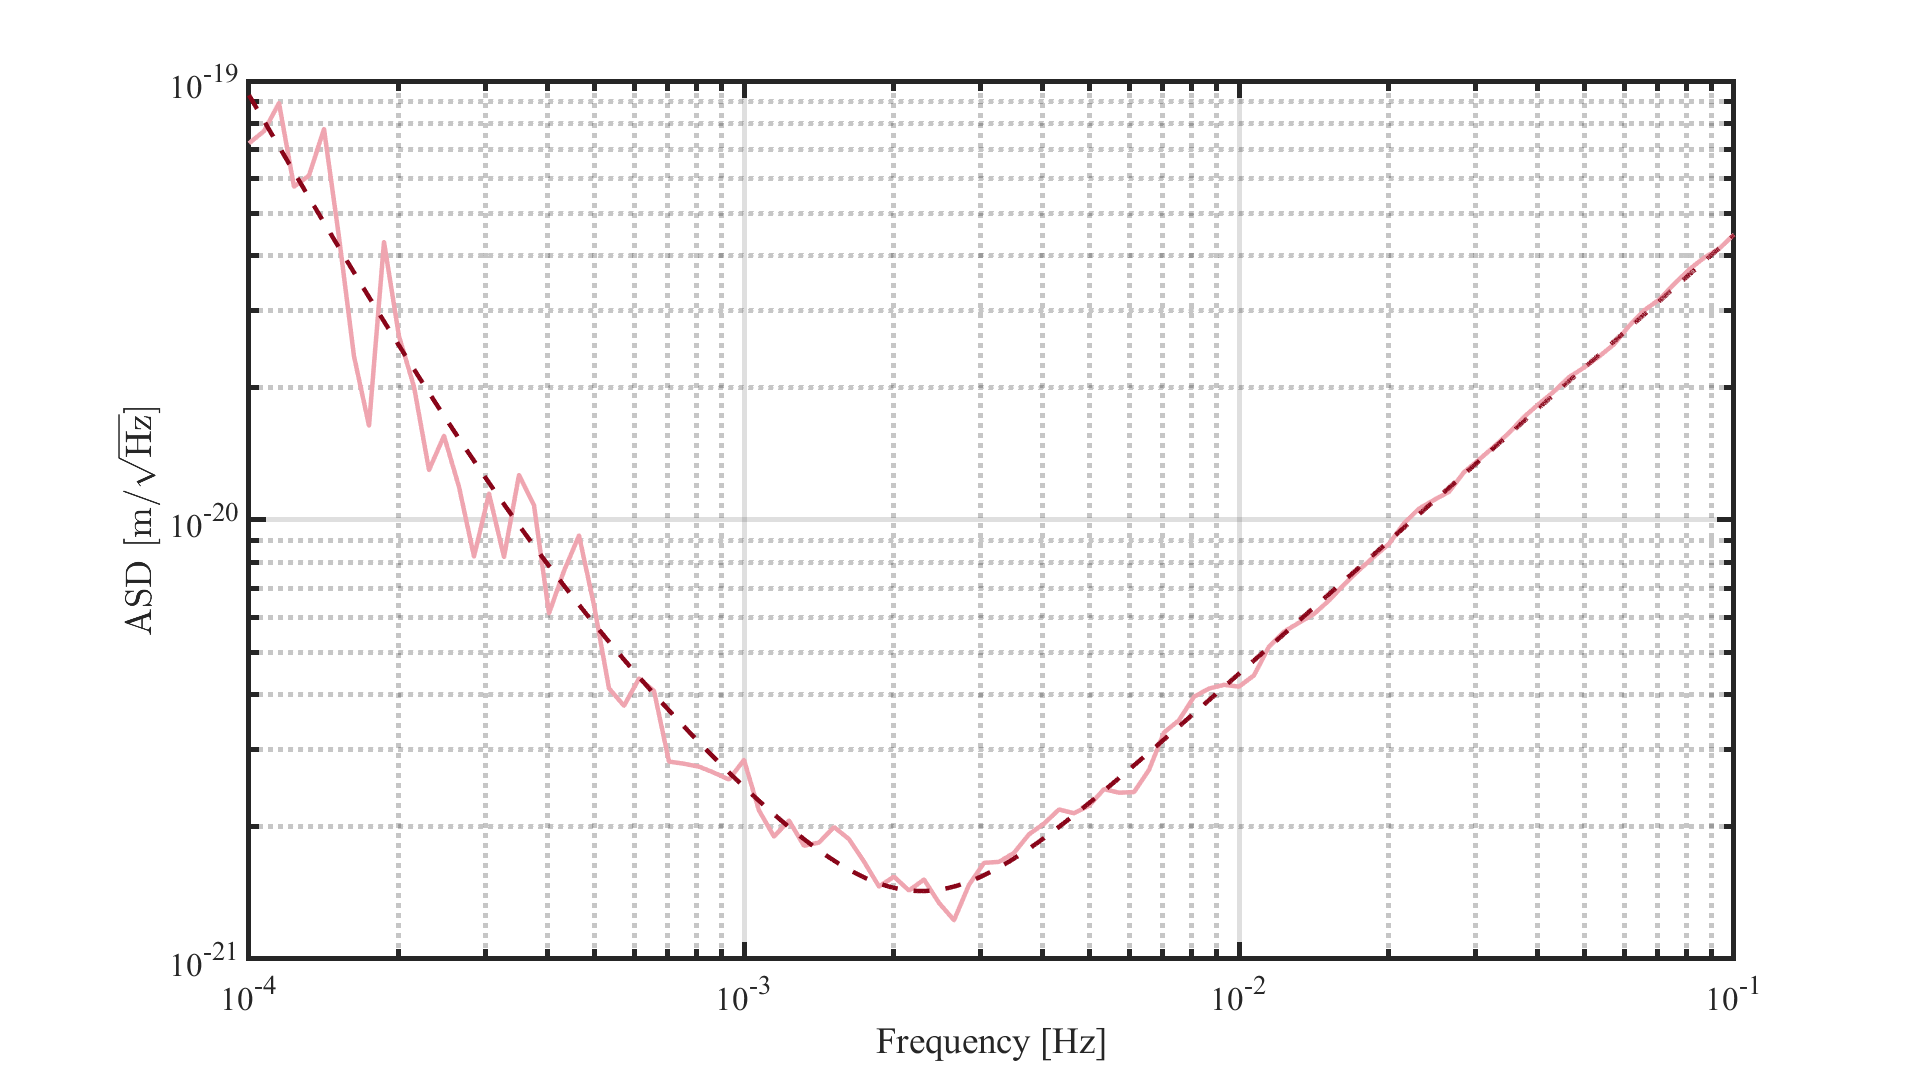

new_figure;
[X_stocha, f_stocha, C_stocha] = lpsd(stochastic_noise_1, ...
    @hann, 1e-4, 1e-1, 100, 1, 1, fs, 0.9);
loglog(f_stocha, sqrt(X_stocha .* C_stocha.PSD), 'linewidth', 2.7, ...
    "LineStyle", "-", "Color", "#EFA5B0"); hold on;
loglog(f, S_n(f), 'linewidth', 2.7, "LineStyle", "--", "Color", "#890519");
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);

We assume that Taiji's single-link measurements include two main sources of noise: a large term due to laser frequency fluctuations and a much smaller term due to other instrumental noises. We assume that the signals measured by the two optical benches on board spacecraft 1 are given by the equations


$$\begin{array}{l}
s_{12} \left(t\right)=p_{21} \left(t-\frac{L_{12} }{c}\right)-p_{12} \left(t\right)+n_{12} \left(t\right),\\
s_{13} \left(t\right)=p_{31} \left(t-\frac{L_{13} }{c}\right)-p_{13} \left(t\right)+n_{13} \left(t\right),
\end{array}$$


where $p_{\mathrm{ij}}$ are laser noises, $n_{\mathrm{ij}}$ are secondary noises, and $c$ is the speed of light. To simplify the analysis, we assume that the two lasers on board each spacecraft $i$ are identical, so that $p_{\mathrm{ij}} =p_{\mathrm{ik}}$. In this model, the measured laser noises can be seen as the result of the mixing (and delaying) of a vector of laser noise sources $\mathit{\mathbf{p}}={\left({\mathit{\mathbf{p}}}_{12}^T ,{\mathit{\mathbf{p}}}_{23}^T ,{\mathit{\mathbf{p}}}_{31}^T \right)}^T$. We consider the 6$N$ column-vector version of the $N\times 6$ matrix $\mathit{\mathbf{Y}}$, which stacks all the measurements as 


$$\mathit{\mathbf{y}}={\left({\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} ,{\mathit{\mathbf{s}}}_{12}^{\mathit{\mathbf{T}}} \right)}^{\mathit{\mathbf{T}}} ,$$


This mixing is represented by a $6N\times 3N$ design matrix $M$, such that the model for $\mathit{\mathbf{y}}$ is


$$\mathit{\mathbf{y}}=\mathit{\mathbf{Mp}}+\mathit{\mathbf{n}},$$


where we set $\mathit{\mathbf{n}}={\left({\mathit{\mathbf{n}}}_{12}^{\mathit{\mathbf{T}}} ,\ldotp \ldotp \ldotp ,{\mathit{\mathbf{n}}}_{32}^{\mathit{\mathbf{T}}} \right)}^{\mathit{\mathbf{T}}}$. Using this assumption, we have


$$\mathit{\mathbf{M}}=\left\lbrack \begin{array}{ccc}
-1 & {\mathit{\mathbf{D}}}_{12}  & 0\\
0 & -1 & {\mathit{\mathbf{D}}}_{23} \\
{\mathit{\mathbf{D}}}_{31}  & 0 & -1\\
-1 & 0 & {\mathit{\mathbf{D}}}_{13} \\
{\mathit{\mathbf{D}}}_{21}  & -1 & 0\\
0 & {\mathit{\mathbf{D}}}_{32}  & -1
\end{array}\right\rbrack ,$$


We assume a static Taiji constellation, that is, $L=3\times {10}^9 \;\mathrm{m}=L_{12} =L_{21} =L_{13} =L_{31} =L_{23} =L_{32}$. Therefore, ${\mathit{\mathbf{D}}}_{12} ={\mathit{\mathbf{D}}}_{21} ={\mathit{\mathbf{D}}}_{13} ={\mathit{\mathbf{D}}}_{31} ={\mathit{\mathbf{D}}}_{23} ={\mathit{\mathbf{D}}}_{32}$.

% --------------------------------------------------------------- %
% Form the single-link measurements of the science interferometer %
% --------------------------------------------------------------- %
% lagrange filter kernel, fractional delay filter, from shaddock
fdf_kernel = fdf(101, L, fs);
laser_freq_noise_1_delayed = filter_pdfree(fdf_kernel, laser_freq_noise_1);
laser_freq_noise_1_matched = match_filter(fdf_kernel, laser_freq_noise_1);
laser_freq_noise_2_delayed = filter_pdfree(fdf_kernel, laser_freq_noise_2);
laser_freq_noise_2_matched = match_filter(fdf_kernel, laser_freq_noise_2);
laser_freq_noise_3_delayed = filter_pdfree(fdf_kernel, laser_freq_noise_3);
laser_freq_noise_3_matched = match_filter(fdf_kernel, laser_freq_noise_3);

